## Modelagm de um sistema dinâmico

## Boas práticas

clear all;          % limpa variaveis
close all;          % fecha figuras
clc;                % limpa a tela

## Lendo os dados do sistema dinâmico real

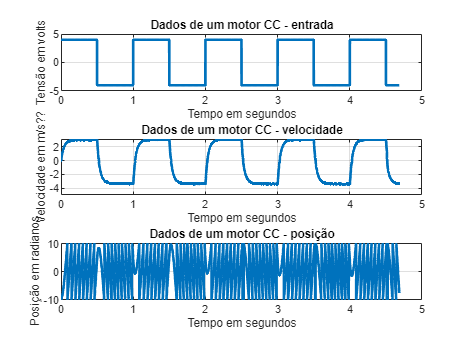

% lendo os dados do arquivo txt
lerDados

% informações do sistema de aquisilção
T = 1e-3;                % taxa de amostragem
N = length(Entrada);     % Número de pontos

% vetor tempo
tempo = linspace(0,N*T,N);

% visualizando os dados
figure(1)

subplot(3,1,1)      % primeiro gráfico em 3 linhas e 1 coluna

plot(tempo,Entrada,'LineWidth',2)
title('Dados de um motor CC - entrada')
xlabel('Tempo em segundos')
ylabel('Tensão em volts')
grid

subplot(3,1,2)      % segundo gráfico gráfico em 3 linhas e 1 coluna

plot(tempo,Omega,'LineWidth',2)
title('Dados de um motor CC - velocidade')
xlabel('Tempo em segundos')
ylabel('Velocidade em m/s??')
grid

subplot(3,1,3)      % terceiro gráfico em 3 linhas e 1 coluna

plot(tempo,Posicao,'LineWidth',2)
title('Dados de um motor CC - posição')
xlabel('Tempo em segundos')
ylabel('Posição em radianos')
grid

## Criando um modelo de laplace

O sinal de entrada U(s) foi aplicado a um sistemna cuja função de rtansferencia gerou o sinal omega(s). Logo entre entrada e saida é dada pela função de transferencia:

omega(s)/U(s) = Km/s+Pm. Neste caso supomos ser de primeira ordem pelo aspecto geral do sinal Rotação.

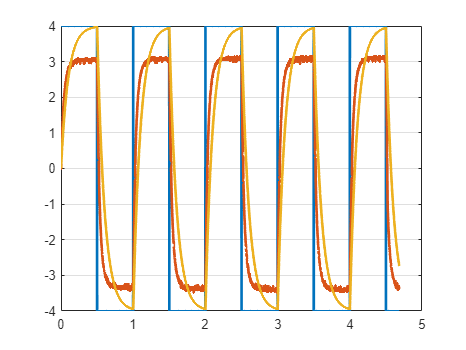

% valores iniciais
Km = 10;             % ganho inicial
Pm = 10;             % polo inicial

% função de transferencia -> modelo de laplace
Gp = tf(Km,[1,Pm]);

% simulando o modelo com a mesma entrada do sistema real
ym = lsim(Gp, Entrada, tempo);

% comparando os dados simulados com os dados reais

figure(2)
plot(tempo,Entrada,tempo,Omega,tempo,ym,'LineWidth',2);
grid;

## Ajustando um modelo em laplace

x0 = [1 1];                 % consição inicial Km = 1 e Pm = 1

X = fminsearch(@(x) ErroQuadratico(x,Omega,tempo,Entrada), x0)

X =    22.4732   28.0882


## Comparando modelo com dados reais

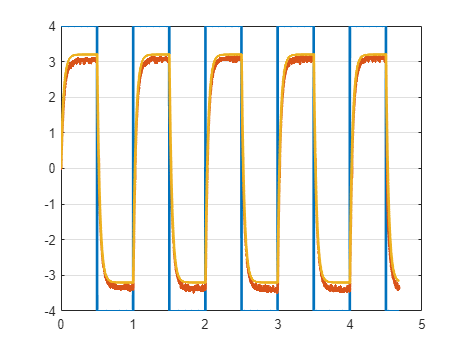

% atualizando valores iniciais
Km = X(1);             % ganho inicial
Pm = X(2);             % polo inicial

% função de transferencia -> modelo de laplace
Gp = tf(Km,[1,Pm]);

% simulando o modelo com a mesma entrada do sistema real
ym = lsim(Gp, Entrada, tempo);

% comparando os dados simulados com os dados reais
figure(3)
plot(tempo,Entrada,tempo,Omega,tempo,ym,'LineWidth',2);
grid;